# exercise 1

%% for z 
syms x y z psi
axes = z;           % The axis which the rotation is performed on (x,y,z)
angle = psi;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_z = Rot(axes , angle , dim_tree_four, deg)

 
Rot_z =
 
                         [cos(psi)    -sin(psi)    0]
                         [                          ]
                         [sin(psi)    cos(psi)     0]
                         [                          ]
                         [   0            0        1]


%% for x
syms x y z phi
axes = x;           % The axis which the rotation is performed on (x,y,z)
angle = phi;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_x = Rot(axes , angle , dim_tree_four, deg)

 
Rot_x =
 
                         [1       0            0    ]
                         [                          ]
                         [0    cos(phi)    -sin(phi)]
                         [                          ]
                         [0    sin(phi)    cos(phi) ]


%% for y
syms x y z theta
axes = y;           % The axis which the rotation is performed on (x,y,z)
angle = theta;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_y = Rot(axes , angle , dim_tree_four, deg)

 
Rot_y =
 
                       [cos(theta)     0    sin(theta)]
                       [                              ]
                       [     0         1        0     ]
                       [                              ]
                       [-sin(theta)    0    cos(theta)]


## Exercise 1.1

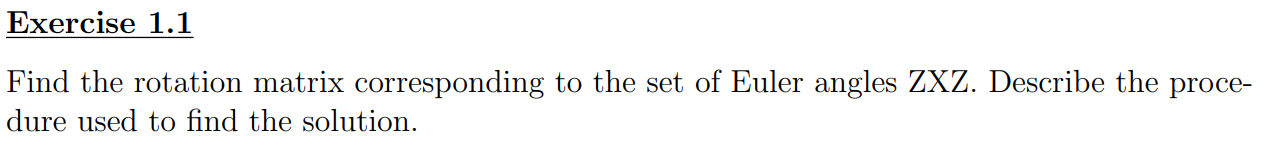


Rot_zxz = Rot_z * Rot_x * Rot_z

 
Rot_zxz =
 
        [        2           2
        [cos(psi)  - sin(psi)  cos(phi) ,

                                                                           ]
        -cos(psi) sin(psi) - sin(psi) cos(phi) cos(psi) , sin(psi) sin(phi)]

        [
        [cos(psi) sin(psi) + sin(psi) cos(phi) cos(psi) ,

                 2           2                              ]
        -sin(psi)  + cos(psi)  cos(phi) , -cos(psi) sin(phi)]

        [sin(psi) sin(phi) , cos(psi) sin(phi) , cos(phi)]


## Exercise 1.2

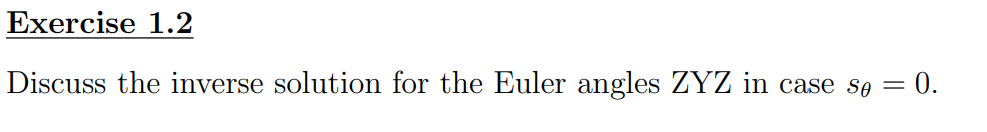

%% for y 
theta = 0;




Rot_zyz = simplify(subs(Rot_z) * subs(Rot_y) * subs(Rot_z))

Unrecognized function or variable 'isNullObjOrSeq'.

Error in mupadengine/evalin_internal

Error in sym/simplify (line 66)
    criterion = evalin_internal(symengine, 'Simplify::defaultValuation');



Rot_zz = simplify(Rot_z*Rot_z)


inv(Rot_zz)

## Exercise 1.3

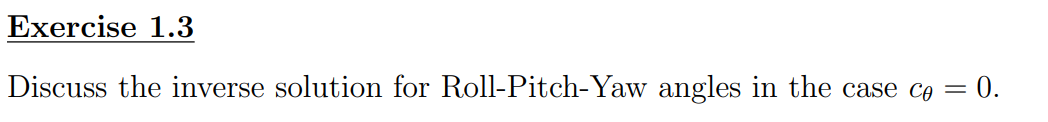

% lokink at ZYX

theta = 90*pi/180;;
Rot_zyz = simplify(subs(Rot_z) * subs(Rot_y) * subs(Rot_x))



## Exercise 1.4

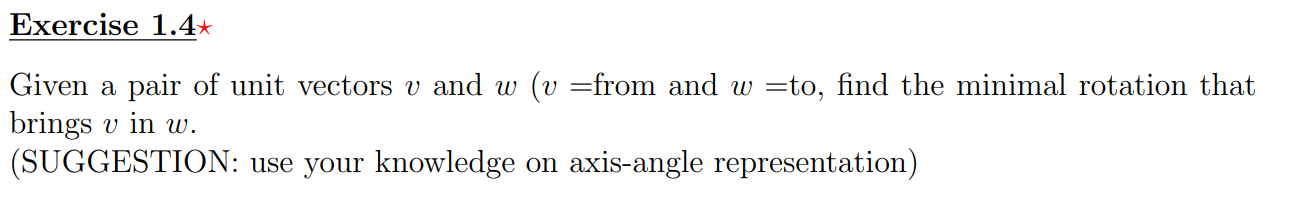

syms v_1 v_2 v_3 w_1 w_2 w_3
v = [1 ; 0 ; 0];
w = [0 ; 1 ; 0];


% Determining the axix wee wont to rotate it about
axis = cross(v,w)

% Angle we want to rotate 
theta = acos(dot(v,w)/norm(v)*norm(w))

## Exercise 1.5

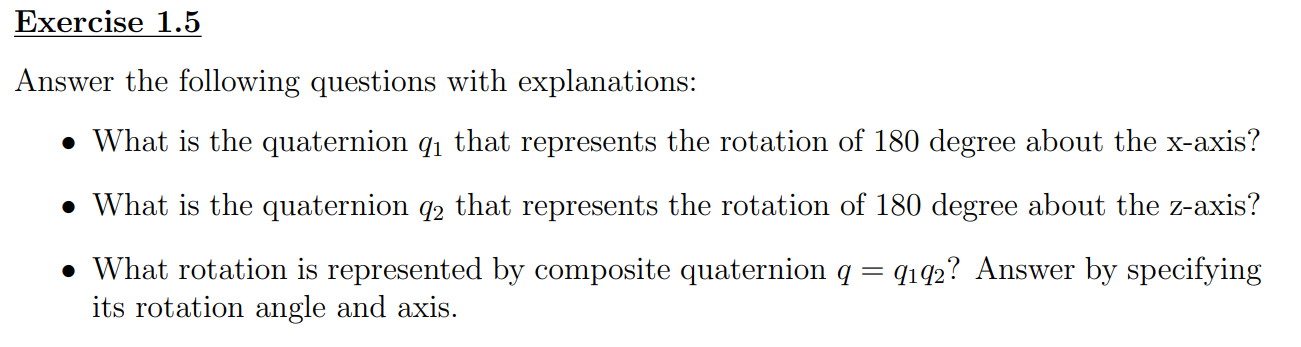

Answers:

- q1 = (a1 b1 c1 d1):  The elements b, c, and d are the "vector part" of the quaternion, and can be thought of as a vector about which rotation should be performed. The element a is the "scalar part" that specifies the amount of rotation that should be performed about the vector part.

theta = pi;
v_x = 1; v_y = 0; v_z = 0;

q1 =[cos(0.5*theta) ; v_x*sin(0.5*theta) ; v_y*sin(0.5) ; v_z*sin(0.5*theta)]

a = q1(1)
b = q1(2)
c = q1(3)
d = q1(4)
theta = pi;



- q2

theta = pi;
v_x = 0; v_y = 0; v_z = 1;

q2 =[cos(0.5*theta) ; v_x*sin(0.5*theta) ; v_y*sin(0.5) ; v_z*sin(0.5*theta)]

a = q2(1)
b = q2(2)
c = q2(3)
d = q2(4)


- qq



qq = quatmultiply(q1',q2')


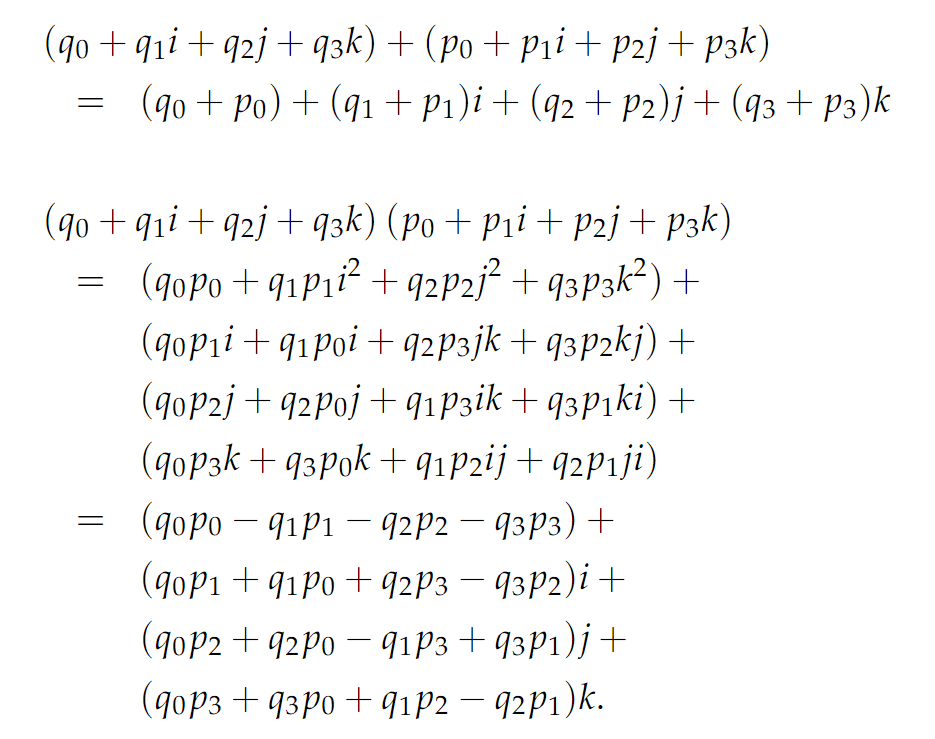

## Exercise 1.6

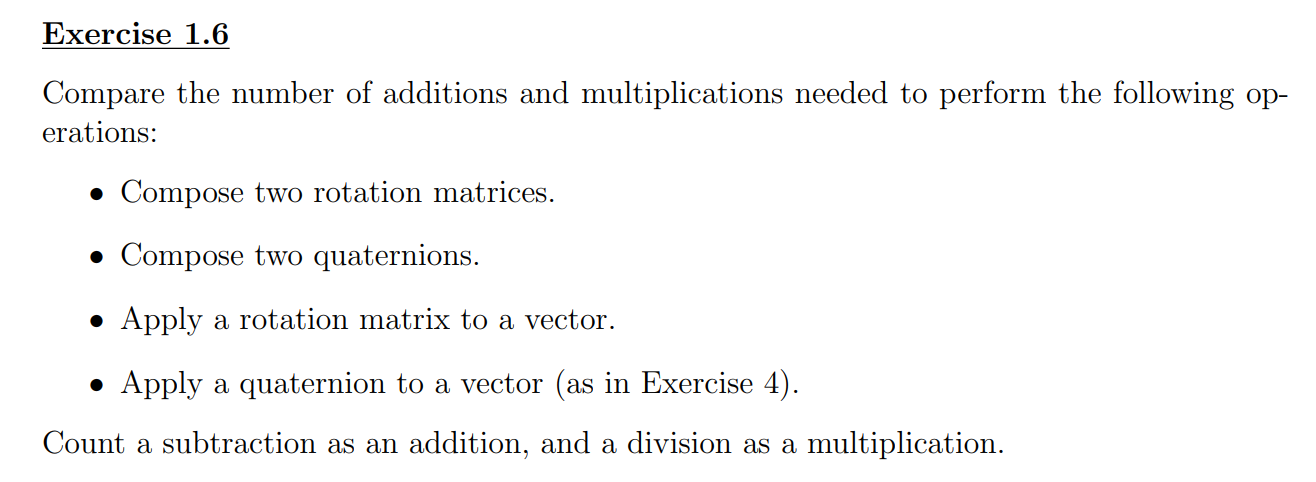

Answers:

- compose two ratation matrices:


syms a b c d e f g h i1 a2 b2 c2 d2 e2 f2 g2 h2 i2


m12 = [ a , b , c;
       d , e , f;
       g , h, i1 ]


m22 = [ a2 , b2 , c2;
       d2 , e2 , f2;
       g2 , h2, i2 ]

m12*m22

% there are 18 additions and 27 multiplications




- compose two quaternion 


q =[a ; b ; c ; d]

q2 =[a2 ; b2 ; c2 ; d2]

%quatmultiply(q,q2)

% 16 mulitplicatons and 15 additions


- Apply a rotation matrix to a vector:

rot = [ a , b , c;
        d , e , f;
        g , h, i1 ];
 
v = [a2 ; b2 ; c2];

rot * v

% 9 multiplications og 6 additions


- Apply a quaternion to a vector:

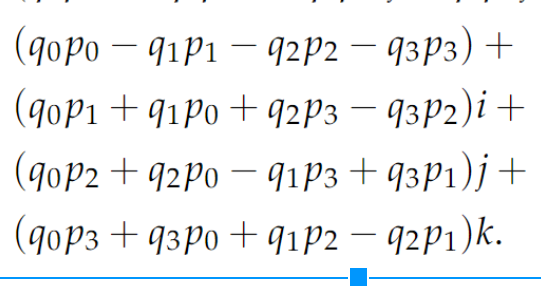

syms v1 v2 v3 a b c d
v = [v1 ; v2 ; v3];
% inserts an extra element in the vector
v = [0 ; v1 ; v2 ; v3];

q = [a  ; b ; c ; d]


qv = [q(1)*v(1) - q(2)*v(2) - q(3)*v(3) - q(4)*v(4);
      q(1)*v(2) + q(2)*v(1) + q(3)*v(4) - q(4)*v(3);
      q(1)*v(3) + q(3)*v(1) - q(2)*v(4) + q(4)*v(2);
      q(1)*v(4) + q(4)*v(1) + q(2)*v(3) - q(3)*v(2)]


% 12 multiplications 8 additions


% slide 84


# Exercise 2

clear; clc;

Rotation matrices:

%% for z 
syms x y z psi
axes = z;           % The axis which the rotation is performed on (x,y,z)
angle = psi;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_z = Rot(axes , angle , dim_tree_four, deg)

 
Rot_z =
 
                         [cos(psi)    -sin(psi)    0]
                         [                          ]
                         [sin(psi)    cos(psi)     0]
                         [                          ]
                         [   0            0        1]


%% for x
syms x y z phi
axes = x;           % The axis which the rotation is performed on (x,y,z)
angle = phi;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_x = Rot(axes , angle , dim_tree_four, deg)

 
Rot_x =
 
                         [1       0            0    ]
                         [                          ]
                         [0    cos(phi)    -sin(phi)]
                         [                          ]
                         [0    sin(phi)    cos(phi) ]


%% for y
syms x y z theta
axes = y;           % The axis which the rotation is performed on (x,y,z)
angle = theta;    % the angle which is used for rotation (If Transformation is used - just type in a random angle) 
dim_tree_four = 3;  % Size of the rotation matrix, normal is it 3*3 but for homogeneous 4*4  (3 eller 4)
deg = 0;            % If degrees(deg=1), radianer-> (deg=0)

Rot_y = Rot(axes , angle , dim_tree_four, deg)

 
Rot_y =
 
                       [cos(theta)     0    sin(theta)]
                       [                              ]
                       [     0         1        0     ]
                       [                              ]
                       [-sin(theta)    0    cos(theta)]


## Excersize 2.1

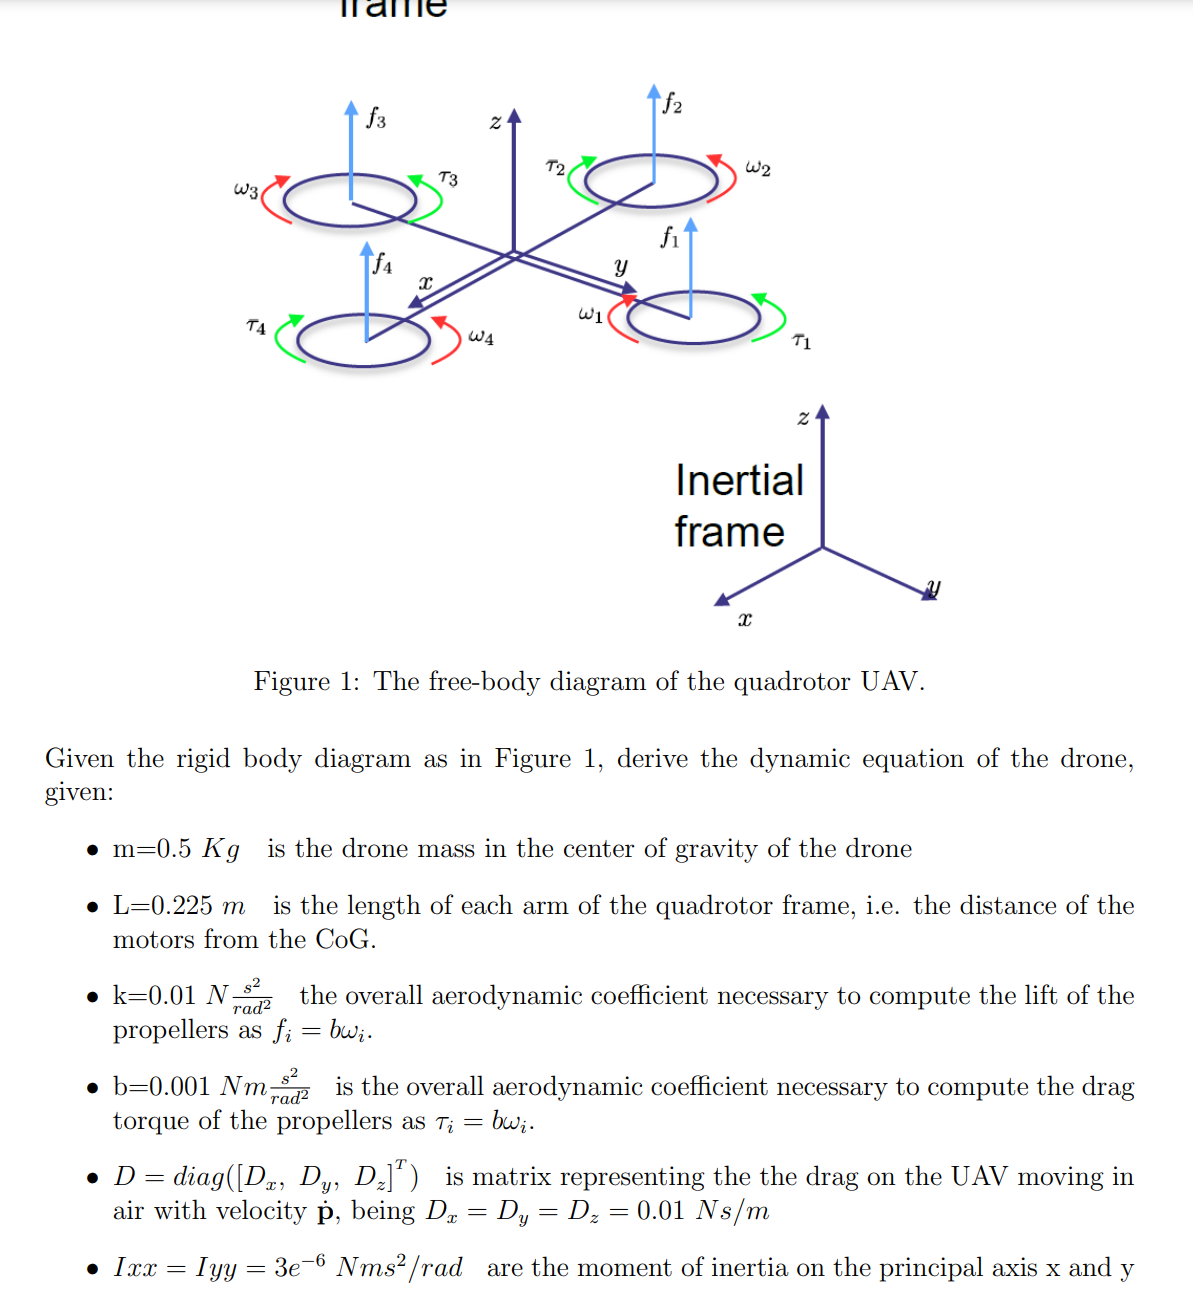

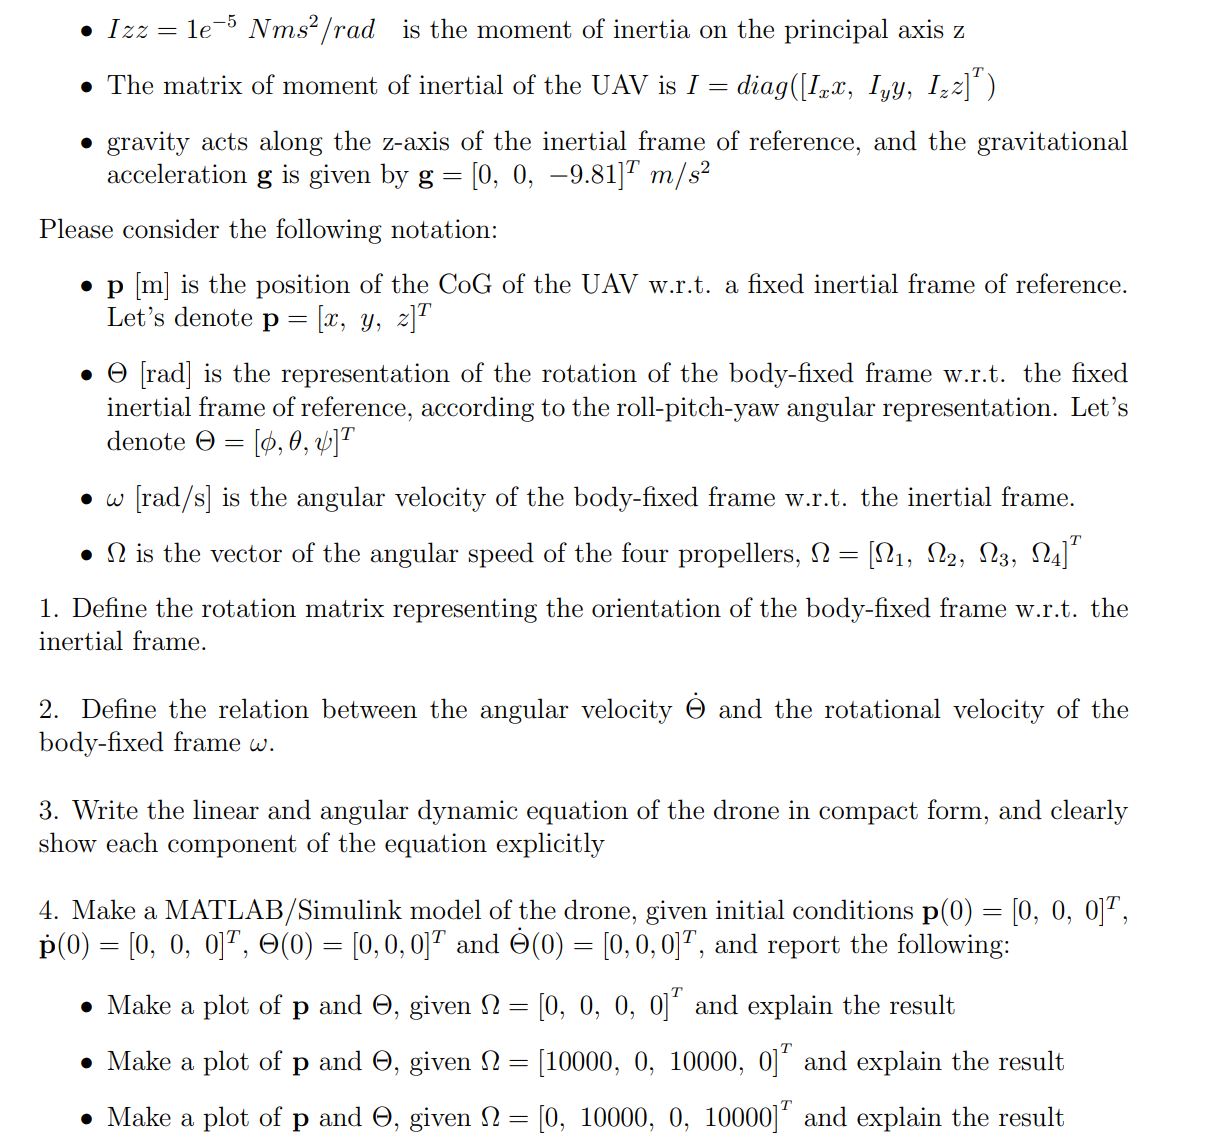

## Exercise 2.1

% zyx
Rot_xyz = Rot_z * Rot_y * Rot_x

 
Rot_xyz =
 
        [cos(psi) cos(theta) ,

        -sin(psi) cos(phi) + cos(psi) sin(theta) sin(phi) ,

        sin(psi) sin(phi) + cos(psi) sin(theta) cos(phi)]

        [sin(psi) cos(theta) ,

        cos(psi) cos(phi) + sin(psi) sin(theta) sin(phi) ,

        -cos(psi) sin(phi) + sin(psi) sin(theta) cos(phi)]

        [-sin(theta) , sin(phi) cos(theta) , cos(phi) cos(theta)]


## Exercise 2.1.2

syms theta phi shi f4 f3 f2 f1 L theta_dot phi_dot psi_dot



% relation between omega and theta
r2t = [1  ,     0     ,     -sin(theta)     ;
       0  , cos(phi)  , cos(theta)*sin(phi) ;
       0  , -sin(phi) , cos(theta)*cos(phi)];


% determine omega
omega = r2t * [phi_dot ; theta_dot ; psi_dot]

 
omega =
 
              [          phi_dot - sin(theta) psi_dot           ]
              [                                                 ]
              [cos(phi) theta_dot + sin(phi) cos(theta) psi_dot ]
              [                                                 ]
              [-sin(phi) theta_dot + cos(phi) cos(theta) psi_dot]





% slide 108

## Exercise 2.1.3

syms K Kd x_dot y_dot z_dot L omega_1 omega_2 omega_3 omega_4 b I_xx I_yy I_zz m g x_dot_dot y_dot_dot z_dot_dot

% slide 56 (PDF)
FB = [0 ; 0 ; omega_1^2 + omega_2^2 + omega_3^2 + omega_4^2] * K

 
FB =
 
                [                      0                      ]
                [                                             ]
                [                      0                      ]
                [                                             ]
                [          2          2          2          2 ]
                [K (omega_1  + omega_2  + omega_3  + omega_4 )]



FD = [-Kd*x_dot ; -Kd*y_dot ; -Kd*z_dot]

 
FD =
 
                                  [-x_dot Kd]
                                  [         ]
                                  [-y_dot Kd]
                                  [         ]
                                  [-z_dot Kd]



% slide 58 (PDF)
tau_B = [         L * K* (omega_1^2 - omega_3^2)          ;
                  L * K* (omega_2^2 - omega_4^2)          ;     
         b*(omega_1^2 - omega_2^2 + omega_3^2 - omega_4^2)]

 
tau_B =
 
                [                  2          2               ]
                [          (omega_1  - omega_3 ) K L          ]
                [                                             ]
                [                  2          2               ]
                [          (omega_2  - omega_4 ) K L          ]
                [                                             ]
                [        2          2          2          2   ]
                [(omega_1  - omega_2  + omega_3  - omega_4 ) b]




% omega_ from exercise 2.2
omega

 
omega =
 
              [          phi_dot - sin(theta) psi_dot           ]
              [                                                 ]
              [cos(phi) theta_dot + sin(phi) cos(theta) psi_dot ]
              [                                                 ]
              [-sin(phi) theta_dot + cos(phi) cos(theta) psi_dot]




% slide 59 (PDF)
% the identity matrix
I = [I_xx  ,    0  ,  0  ;
       0   ,  I_yy ,  0  ;
       0   ,    0  , I_zz]

 
I =
 
                            [I_xx     0       0  ]
                            [                    ]
                            [ 0      I_yy     0  ]
                            [                    ]
                            [ 0       0      I_zz]



% massmatrix
m1 = [m , 0 , 0;
     0 , m , 0;
     0 , 0 , m]

 
m1 =
 
                                 [m    0    0]
                                 [           ]
                                 [0    m    0]
                                 [           ]
                                 [0    0    m]




% the rotation matrix from exercise 2.1
R = Rot_xyz

 
R =
 
        [cos(psi) cos(theta) ,

        -sin(psi) cos(phi) + cos(psi) sin(theta) sin(phi) ,

        sin(psi) sin(phi) + cos(psi) sin(theta) cos(phi)]

        [sin(psi) cos(theta) ,

        cos(psi) cos(phi) + sin(psi) sin(theta) sin(phi) ,

        -cos(psi) sin(phi) + sin(psi) sin(theta) cos(phi)]

        [-sin(theta) , sin(phi) cos(theta) , cos(phi) cos(theta)]





% linar dynamics
x_dot_dot1 = [x_dot_dot ; y_dot_dot ; z_dot_dot]

 
x_dot_dot1 =
 
                                  [x_dot_dot]
                                  [         ]
                                  [y_dot_dot]
                                  [         ]
                                  [z_dot_dot]


mx_dot_dot1 = [0 ; 0 ;  -m*g] + R * FB + FD

 
mx_dot_dot1 =
 
        [(sin(psi) sin(phi) + cos(psi) sin(theta) cos(phi)) K %1 - x_dot Kd]

        [(-cos(psi) sin(phi) + sin(psi) sin(theta) cos(phi)) K %1 - y_dot Kd]

        [-g m + cos(phi) cos(theta) K %1 - z_dot Kd]

               2          2          2          2
  %1 := omega_1  + omega_2  + omega_3  + omega_4






omega_dot = I^(-1) * (tau_B - cross(omega, I*omega))

 
omega_dot =
 
        [        2          2                               ]
        [(omega_1  - omega_3 ) K L - I_zz %1 %2 + I_yy %2 %1]
        [---------------------------------------------------]
        [                       I_xx                        ]

        [        2          2                               ]
        [(omega_2  - omega_4 ) K L - I_xx %3 %1 + I_zz %1 %3]
        [---------------------------------------------------]
        [                       I_yy                        ]

        [         2          2          2          2
        [((omega_1  - omega_2  + omega_3  - omega_4 ) b - I_yy %2 %3

                           ]
         + I_xx %3 %2)/I_zz]

  %1 := -sin(phi) theta_dot + cos(phi) cos(theta) psi_dot

  %2 := cos(phi) theta_dot + sin(phi) cos(theta) psi_dot

  %3 := phi_dot - sin(theta) psi_dot




% slide 60 (PDF)
%omega_dot = [tau_phi * I_xx^(-1)  ; tau_theta * I_yy^(-1) ;  tau_spi * I_zz^(-1) ] - []





syms phi_dot theta_dot psi_dot theta phi psi omega_x omega_y omega_z
% isolating thetha dot by multiplying with the inverse matrice
R  = [1  ,      0       , sin(theta);
      0  ,   cos(phi)   , cos(theta)*sin(phi);
      0  ,  -sin(phi)   , cos(theta)*sin(phi)]

 
R =
 
                    [1        0            sin(theta)     ]
                    [                                     ]
                    [0    cos(phi)     sin(phi) cos(theta)]
                    [                                     ]
                    [0    -sin(phi)    sin(phi) cos(theta)]



[phi_dot ; theta_dot ; psi_dot] == (inv(R) * [omega_x ; omega_y ; omega_z])

ans = 3×1 logical array
   0
   0
   0


## 2.1.4

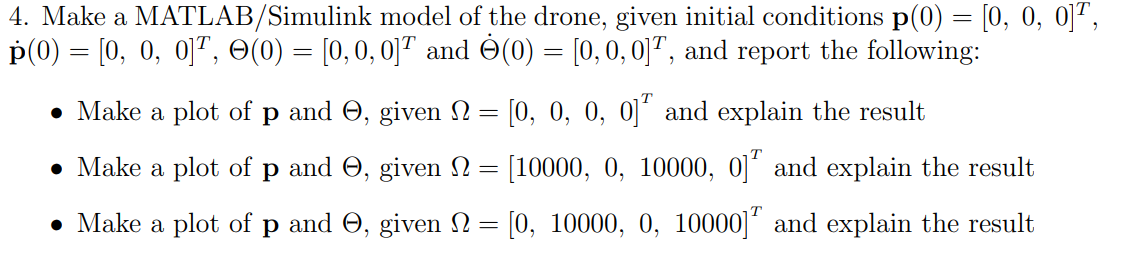

syms x_dot_dot
L1 = m*x_dot_dot1 == [0 ; 0 ;  -m*g] + R * FB + FD

L1 = 3×1 logical array
   0
   0
   0




% simulates the model 
% Simulator parameters (RG)
SIM_TIME = 10; 
% Change with the name of the model you are using
SIMULINK_FILENAME = ['ex2'];

% Model paramters
omega_1 = 0;
omega_2 = 0;
omega_3 = 0; 
omega_4 = 0;

I_xx = 3*10^(-6);
I_yy = 3*10^(-6);
I_zz = 1*10^(-5);

phi = 0;
theta = 0;
psi = 0;

g = 9.81;
m = 0.5;
k = 0.01;
l = 0.225; %L
kd = 0.01;
B = 0.001;

switch1 = 1;
%omegas = omega_1 + omega_2 + omega_3 + omega_4;
omega1 = omega_1; omega2 = omega_2; omega3 = omega_3; omega4 = omega_4;

%time = (0:STEP_SIZE:SIM_TIME)';
sim(SIMULINK_FILENAME,SIM_TIME)

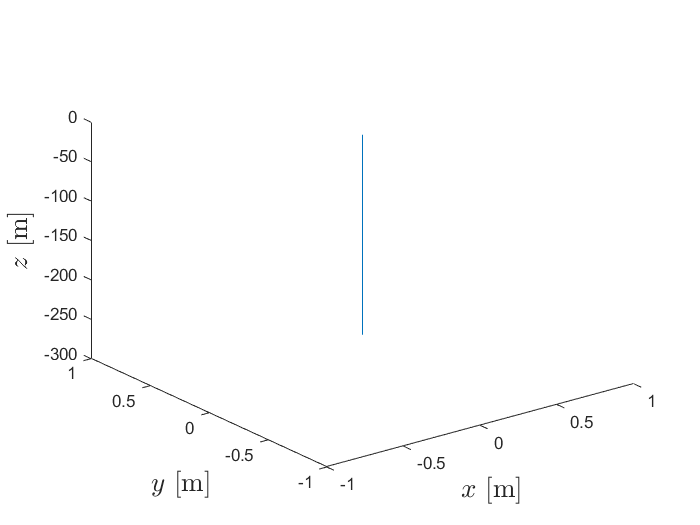


figure
plot3(x.Data,y.Data,z.Data)
ylabel('$y$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
zlabel('$z$ [m]','FontName','times','FontSize',16,'Interpreter','latex')

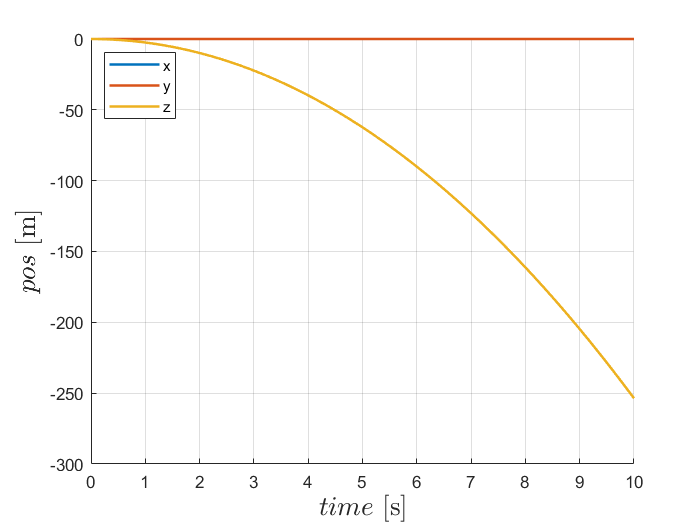


figure
hold on, grid on
plot(x.time,x.Data,'LineWidth',1.5)
plot(x.time,y.Data,'LineWidth',1.5)
plot(x.time,z.Data,'LineWidth',1.5)
ylabel('$pos$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('x','y','z','Location','NorthWest');

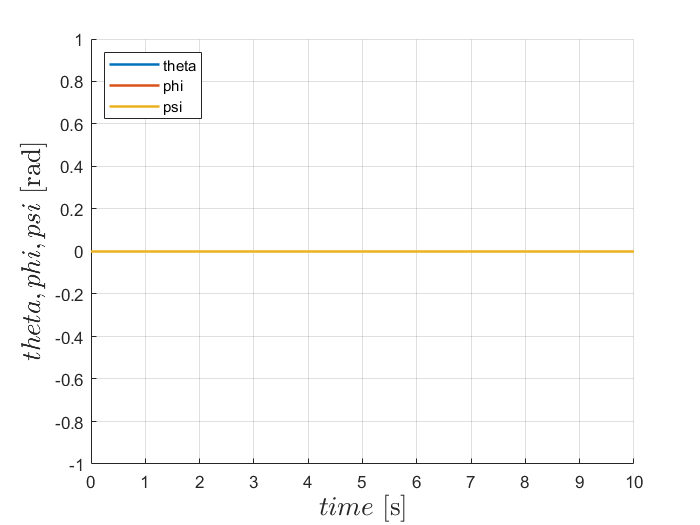




figure
hold on, grid on
plot(x.time,theta_pitch.Data,'LineWidth',1.5)
plot(x.time,phi_roll.Data,'LineWidth',1.5)
plot(x.time,psi_yaw.Data,'LineWidth',1.5)
ylabel(['$theta , phi , psi$ [rad]'],'FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('theta','phi','psi','Location','NorthWest');

% simulates the model 
% Simulator parameters (RG)
SIM_TIME = 10; 
% Change with the name of the model you are using
SIMULINK_FILENAME = ['ex2'];

% Model paramters
omega_1 = 10000;
omega_2 = 0;
omega_3 = 10000; 
omega_4 = 0;

I_xx = 3*10^(-6);
I_yy = 3*10^(-6);
I_zz = 1*10^(-5);

phi = 0;
theta = 0;
psi = 0;

g = 9.81;
m = 0.5;
k = 0.01;
l = 0.225; %L
kd = 0.01;

switch1 = 1;
%omegas = omega_1 + omega_2 + omega_3 + omega_4;
omega1 = omega_1; omega2 = omega_2; omega3 = omega_3; omega4 = omega_4;

sim(SIMULINK_FILENAME,SIM_TIME)


figure
plot3(x.Data,y.Data,z.Data)
ylabel('$y$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
zlabel('$z$ [m]','FontName','times','FontSize',16,'Interpreter','latex')


figure
hold on, grid on
plot(x.time,x.Data,'LineWidth',1.5)
plot(x.time,y.Data,'LineWidth',1.5)
plot(x.time,z.Data,'LineWidth',1.5)
ylabel('$pos$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('x','y','z','Location','NorthWest');


figure
hold on, grid on
plot(x.time,theta_pitch.Data,'LineWidth',1.5)
plot(x.time,phi_roll.Data,'LineWidth',1.5)
plot(x.time,psi_yaw.Data,'LineWidth',1.5)
ylabel(['$theta , phi , psi$ [rad]'],'FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('theta','phi','psi','Location','NorthWest');

% simulates the model 
% Simulator parameters (RG)
SIM_TIME = 10; 
% Change with the name of the model you are using
SIMULINK_FILENAME = ['ex2'];

% Model paramters
omega_1 = 0;
omega_2 = 10000;
omega_3 = 0; 
omega_4 = 10000;

I_xx = 3*10^(-6);
I_yy = 3*10^(-6);
I_zz = 1*10^(-5);

phi = 0;
theta = 0;
psi = 0;

g = 9.81;
m = 0.5;
k = 0.01;
l = 0.225; %L
kd = 0.01;
B = 0.001;

switch1 = 1;
%omegas = omega_1 + omega_2 + omega_3 + omega_4;
omega1 = omega_1; omega2 = omega_2; omega3 = omega_3; omega4 = omega_4;

sim(SIMULINK_FILENAME,SIM_TIME)


figure
plot3(x.Data,y.Data,z.Data)
ylabel('$y$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$x$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
zlabel('$z$ [m]','FontName','times','FontSize',16,'Interpreter','latex')


figure
hold on, grid on
plot(x.time,x.Data,'LineWidth',1.5)
plot(x.time,y.Data,'LineWidth',1.5)
plot(x.time,z.Data,'LineWidth',1.5)
ylabel('$pos$ [m]','FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('x','y','z','Location','NorthWest');




figure
hold on, grid on
plot(x.time,theta_pitch.Data,'LineWidth',1.5)
plot(x.time,phi_roll.Data,'LineWidth',1.5)
plot(x.time,psi_yaw.Data,'LineWidth',1.5)
ylabel(['$theta , phi , psi$ [rad]'],'FontName','times','FontSize',16,'Interpreter','latex')
xlabel('$time$ [s]','FontName','times','FontSize',16,'Interpreter','latex')
legend('theta','phi','psi','Location','NorthWest');

# exercise 3

## Exercise 3.1

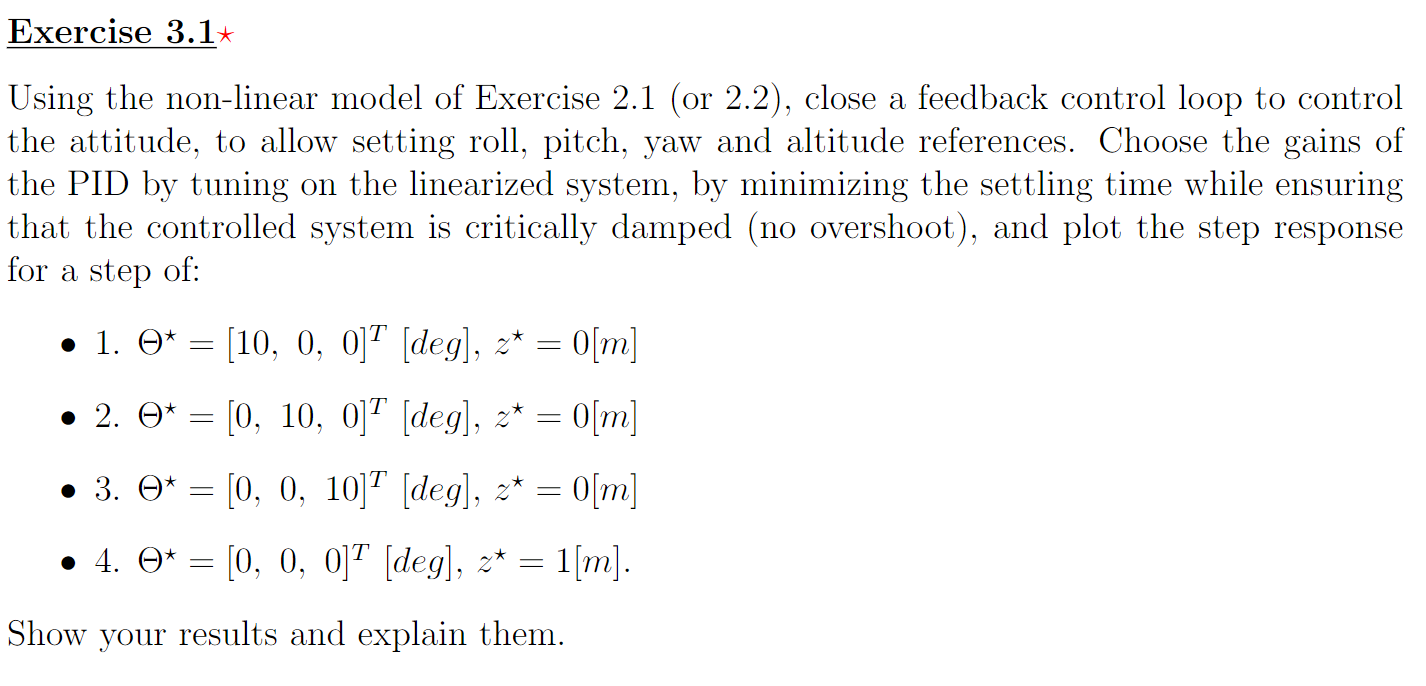

switch1 = 0;

I_xx = 3*10^(-6);
I_yy = 3*10^(-6);
I_zz = 1*10^(-5);

phi = 0;
theta = 0;
psi = 0;

g = 9.81;
m = 0.5;
k = 0.01;
l = 0.225; %L
kd = 0.01;
B = 0.001;

z = sqrt(m*g/(4*k))

z = 11.0736

% definerer gætet
x0 = zeros(12,1);
u0 = z*ones(4,1);% 1/4 g sqrt(m*g/(4*k))
y0 = zeros(6,1);

% fixed parametrer -> kan ikke ændre sig  
ix = [];    % x kan ændre sig derfor tom
iu = [1,2,3,4]; % kan ikke ændre sig for begge input derfor [1, 2]
iy = [];    % y kan ændre sig derfor tom
disp('The stationary states are given by')

The stationary states are given by


[xss,uss,yss] = trim('ex2',x0,u0,y0)

Maximum number of function evaluations exceeded;
increase OPTIONS(14)


xss =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


uss =    11.0736
   11.0736
   11.0736
   11.0736


yss =      0
     0
     0




%xss = zeros(12,1);
%uss = z*ones(4,1);% 1/4 g sqrt(m*g/(4*k))

% lineariserede model ud fra simulink og stationære punkter
[A,B,C,D] = linmod('ex2',xss,uss);



state_space = ss(A,B,C,D)

state_space =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      0      0      0      0      0      0      1      0      0
   x2       0      0      0      0      0      0      0      0      0      0      1      0
   x3       0      0      0      0      0      0      0      0      0      0      0      1
   x4       0      0      0      0      0      1      0      0      0      0      0      0
   x5       0      0      0      0      0      0      0      0      1      0      0      0
   x6       0      0      0      0      0      0      0      0      0      0      0      0
   x7       0      0      0      0      0      0      0      0      0      0      0      0
   x8       0      0      0      0      0      0      1      0      0      0      0      0
   x9       0      0      0      0      0      0      0      0      0      0      0      0
   x10      0      0      0      0      0      0      0      0     

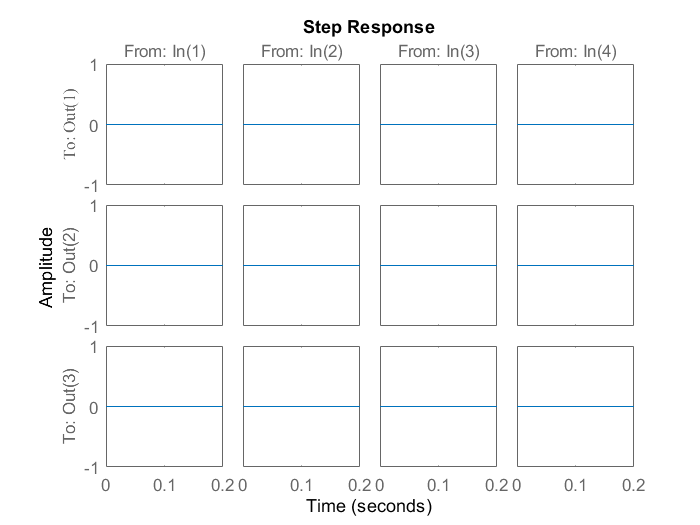



step(state_space)

## Exercise 3

SIMULINK_FILENAME ="ex_pid"

SIMULINK_FILENAME = "ex_pid"


phi_set = 10;
theta_set = 0;
psi_set = 0;
z_set = 0;

%sim(SIMULINK_FILENAME,SIM_TIME)

u_0 = u0

u_0 =    11.0736
   11.0736
   11.0736
   11.0736



Ax = A;
Bx = B;
Cx = C;
Dx = D;






